Dane - pozyskane z platformy kaggle - "HBO Max TV Shows and Movies" (Movies and TV Shows listings on HBO Max (May, 2022))

Zostały wcześniej uporządkowane usuwając przy tym puste pola oraz pola , w przypadku których nie było wszystkich danych 

Dla pierwszych dwóch częsci projektu sprawdzamy korelacje wpierw dla takich zmiennych jak ocana imdb a oceną tmdb oraz korelacje dla zmiennych oceny imdb a rokiem wydania filmu.

W obu przupadkach odrzuciliśmy hipotezę zerową ,która mówiła o braku zależności z czego dla pierwszego przypadku krzywa korelacji pokazała ,iż istnieje korelacja dodatnia zaś w drugim przypadku istnieje korelacja ujemna. 

Niestety dla obu wyliczonych korelacji wyliczony współczynnik determinacji był mniejszy od 0,5 co świadczy o wyjaśnianiu mniej niż 50% zmienności.

W kolejnej części projektu sprawdzana była zależność oceny imdb a rodzajem filmu/serialu. W tym przypadku nie wykryto zależności pomiedzy tymi zmiennymi co dobrze świadczy o procesie dobierania tejże oceny. Rodzaj filmu/serialu nie powinna wpływać na końcową ocenę 

produkcji ,ale inne właściwości filmu.

Ostatnia część porównuje średnią ocen imdb oraz tmdb dla polskich produkcji. Pomimo różnic ocen średnia wynosiła tyle samo i wynosiła 7,17 co nie jest złym wynikiem. Trzeba jednak pamiętać ,iż jeśli chodzi o polskie produkcje to próba w naszym przypadku była mała przez co nie można stwierdzić ,iż jest to wartość reprezentatywna. 

**Czy wystepuje korelacja pomiędzy oceną imbd a wynikiem tmdb ?**

**H0: Nie ma zależności pomiędzy zmiennym**

**H1: Istnieje zależność pomiędzy zmiennymi**

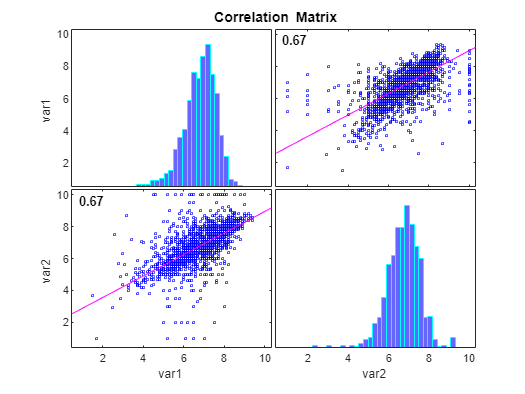

rxy_Pearson =     1.0000    0.6721
    0.6721    1.0000


Pvalue_Pearson =      1     0
     0     1


clearvars
titles = readtable('tabela2.xlsx');
T = [titles.imdb_score,titles.tmdb_score];
[rxy_Pearson,Pvalue_Pearson] = corrplot(T) %zmienne ilościowe dlatego możemy wykonać metoda Pearson

Współczynnik determinacji 

determinajca_Pearsona = 100*rxy_Pearson.^2

determinajca_Pearsona2 =   100.0000   45.1737
   45.1737  100.0000


**Odpowiedź: **Wartośc pvalue = 0 <0,05 co oznacza ,że wynik jest istotny statystycznie, odrzucamy H0 co oznacza ,że istnieje zależność pomiędzy zmiennymi jednak wyliczając współczynnik determinacji = 45,1737% jego jest poniżej 0,5, to regresja wyjaśnia tylko mniej niż 50% zmienności.

**Czy istenieje korelacja pomiędzy ocena imdb a rokiem premiery.**

**H0: Nie ma zależności pomiędzy zmiennym**

**H1: Istnieje zależność pomiędzy zmiennymi**

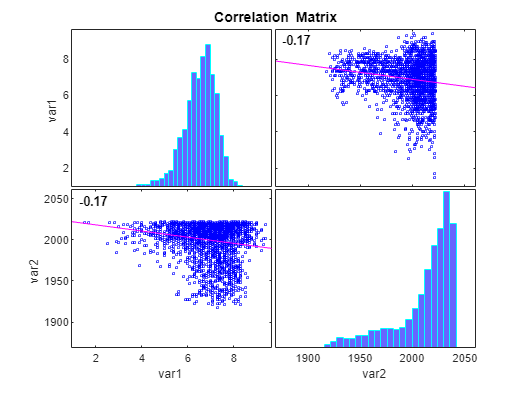

rxy_Pearson2 =     1.0000   -0.1693
   -0.1693    1.0000


Pvalue_Pearson2 =     1.0000    0.0000
    0.0000    1.0000


T2 = [titles.imdb_score,titles.release_year];
[rxy_Pearson2,Pvalue_Pearson2] = corrplot(T2)

Współczynnik determinacji 

determinajca_Pearsona2 = 100*rxy_Pearson2.^2

determinajca_Pearsona =   100.0000    2.8654
    2.8654  100.0000


**Odpowiedź: **Wartośc pvalue = 0 <0,05 co oznacza ,że wynik jest istotny statystycznie, odrzucamy H0 co oznacza ,że istnieje zależność pomiędzy zmiennymi jednak wyliczając współczynnik determinacji = 2,8654% jego jest poniżej 0,5, to regresja wyjaśnia tylko mniej niż 50% zmienności.

**Czy istenieje zależność pomiędzy ocena typem filmu a jego oceną imdb.**

**H0: wartości są niezależne**

**H1: są zależne **

[table1,chi2,p] = crosstab(titles.genres,titles.imdb_score)

table1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     1     0     1     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     1     0     0     0     0     1     0     1     0     0     3     1     2     1     0     2     3     4     1     3     6     2     8     5     5     6     7     3     3
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

chi2 = 9.0603e+04

p = 6.9715e-262

**Odpowiedź: **Wartość p < 0,05 co informuje o braku odrzucenia H0. Sugeruje to ,iż nie ma zależności pomiędzy typem filmu a jego oceną imdb

**Sprawdźmy czy dla kraju produkcji PL średnie ocen imdb oraz tmdb są równe**

**H0: średnie są równe**

**H1:  średnie różnia się **

PL_imdb = titles.imdb_score(titles.production_countries == "['PL']");
PL_tmdb = titles.imdb_score(titles.production_countries == "['PL']");

ans = 7.1714

Sprawdzamy czy rozkład zmiennych jest rozkładem normlanym 

Normalnosc_imdb = normalitytest(PL_imdb(:,1)')

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.4272 	     0.9932                 1 
KS Stephens Modification       0.4774 	     0.1500                 1 
KS Marsaglia Method            0.4272 	     0.9783                 1 
KS Lilliefors Modification     0.1615 	     0.2000                 1 
Anderson-Darling Test          0.2693 	     0.6800                 1 
Cramer- Von Mises Test         0.0349 	     0.7723                 1 
Shapiro-Wilk Test              0.9360 	     0.6932                 1 
Shapiro-Francia Test           0.9532 	     0.7778                 1 
Jarque-Bera Test               0.5027 	     0.7778                 1 
DAgostino & Pearson Test          NaN 	        NaN                 0 


Normalnosc_imdb =     0.4272    0.9932    1.0000
    0.4774    0.1500    1.0000
    0.4272    0.9783    1.0000
    0.1615    0.2000    1.0000
    0.2693    0.6800    1.0000
    0.0349    0.7723    1.0000
    0.9360    0.6932    1.0000
    0.9532    0.7778    1.0000
    0.5027    0.7778    1.0000
       NaN       NaN         0


Normalnosc_tmdb = normalitytest(PL_tmdb')

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.4272 	     0.9932                 1 
KS Stephens Modification       0.4774 	     0.1500                 1 
KS Marsaglia Method            0.4272 	     0.9783                 1 
KS Lilliefors Modification     0.1615 	     0.2000                 1 
Anderson-Darling Test          0.2693 	     0.6800                 1 
Cramer- Von Mises Test         0.0349 	     0.7723                 1 
Shapiro-Wilk Test              0.9360 	     0.6932                 1 
Shapiro-Francia Test           0.9532 	     0.7778                 1 
Jarque-Bera Test               0.5027 	     0.7778                 1 
DAgostino & Pearson Test          NaN 	        NaN                 0 


Normalnosc_tmdb =     0.4272    0.9932    1.0000
    0.4774    0.1500    1.0000
    0.4272    0.9783    1.0000
    0.1615    0.2000    1.0000
    0.2693    0.6800    1.0000
    0.0349    0.7723    1.0000
    0.9360    0.6932    1.0000
    0.9532    0.7778    1.0000
    0.5027    0.7778    1.0000
       NaN       NaN         0


Tak jak widzimy są to rozkłady normalne, natomiast zmienne są powiązane przechodzimy w takim przypadku do testu

[h,p,ci,stats] = ttest2(PL_imdb,PL_tmdb)

h = 0

p = 1

ci =    -0.6578
    0.6578


stats = struct with fields:
    tstat: 0
       df: 12
       sd: 0.5648


**Odpowiedź: **Na podstawie wartości h=0 nie mamy podstaw do odrzucenia H0, średnie sa równe.